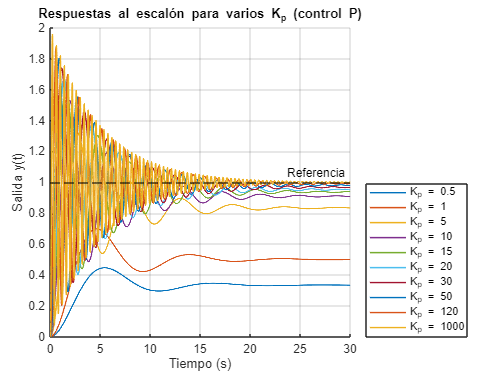

%% ACTIVIDAD: Controlador P (barrido de Kp)
clear; clc; close all

% Planta
num = 0.25;
den = [1 0.4 0.25];
G = tf(num, den);

% Vector de ganancias (10+ valores)
Kp_vec = [0.5 1 5 10 15 20 30 50 120 1000]';

% Prealocación de resultados
nK   = numel(Kp_vec);
tr   = nan(nK,1);
ts   = nan(nK,1);
Mp   = nan(nK,1);     % Overshoot (%)
p1   = strings(nK,1); % polos (como texto para tabla)
p2   = strings(nK,1);
p3   = strings(nK,1);

% Figura: respuestas al escalón superpuestas
figure('Name','Respuestas al escalón (P)');
hold on; grid on
title('Respuestas al escalón para varios K_p (control P)');
xlabel('Tiempo (s)'); ylabel('Salida y(t)');

cm = lines(nK); % paleta de colores

for i = 1:nK
    Kp = Kp_vec(i);
    C  = Kp;                       % Control P
    T  = feedback(C*G, 1);         % T(s) = (C*G)/(1+C*G)

    % Métricas de tiempo
    info = stepinfo(T);            % RiseTime, SettlingTime, Overshoot, etc.
    tr(i) = info.RiseTime;
    ts(i) = info.SettlingTime;
    Mp(i) = info.Overshoot;        % En porcentaje

    % Polos de lazo cerrado
    pp = pole(T);
    % guardar como strings para la tabla (hasta 3 polos en esta planta)
    p1(i) = string(sprintf('%.4f%+.4fi', real(pp(1)), imag(pp(1))));
    if numel(pp) >= 2, p2(i) = string(sprintf('%.4f%+.4fi', real(pp(2)), imag(pp(2)))); end
    if numel(pp) >= 3, p3(i) = string(sprintf('%.4f%+.4fi', real(pp(3)), imag(pp(3)))); end

    % Respuesta al escalón
    t = 0:0.01:30;
    [y, ~] = step(T, t);
    plot(t, y, 'LineWidth', 1.2, 'Color', cm(i,:));
end
yline(1,'k--','Referencia');

legend(compose('K_p = %g', Kp_vec), 'Location','southeastoutside');

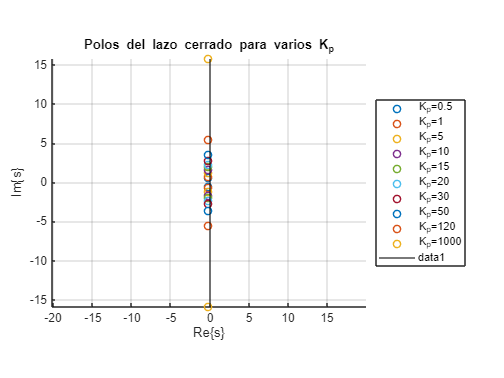


% Figura: polos en el plano-s (diagrama)
figure('Name','Polos en el plano-s (P)');
hold on; grid on; axis equal
title('Polos del lazo cerrado para varios K_p');
xlabel('Re\{s\}'); ylabel('Im\{s\}');

for i = 1:nK
    Kp = Kp_vec(i);
    C  = Kp;
    T  = feedback(C*G,1);
    pp = pole(T);
    plot(real(pp), imag(pp), 'o', 'MarkerSize',6, 'LineWidth',1.2, ...
        'DisplayName', sprintf('K_p=%g',Kp), 'Color', cm(i,:));
end
legend('Location','eastoutside');
xline(0,'k-'); % eje imaginario


% Tabla de resultados
Resultados = table(Kp_vec, tr, ts, Mp, p1, p2, p3, ...
    'VariableNames', {'Kp','t_r_s','t_s_s','OS_percent','polo_1','polo_2','polo_3'});

disp('================ TABLA CONTROL P ================');

================ TABLA CONTROL P ================


disp(Resultados);

     Kp      t_r_s      t_s_s     OS_percent          polo_1                polo_2          polo_3
    ____    ________    ______    __________    __________________    __________________    ______

     0.5      2.2212    18.188      33.711      "-0.2000+0.5788i"     "-0.2000-0.5788i"       ""  
       1      1.8421    19.457       39.59      "-0.2000+0.6782i"     "-0.2000-0.6782i"       ""  
       5     0.96745    18.791      59.249      "-0.2000+1.2083i"     "-0.2000-1.2083i"       ""  
      10     0.69138    19.342      68.253      "-0.2000+1.6462i"     "-0.2000-1.6462i"       ""  
      15     0.56359    19.186      72.916      "-0.2000+1.9900i"     "-0.2000-1.9900i"       ""  
      20     0.48695    19.402      75.931      "-0.2000+2.2825i"   


% Guardar CSV para el informe
writetable(Resultados, 'resultados_P.csv');
disp('Archivo "resultados_P.csv" guardado en el directorio actual.');

Archivo "resultados_P.csv" guardado en el directorio actual.


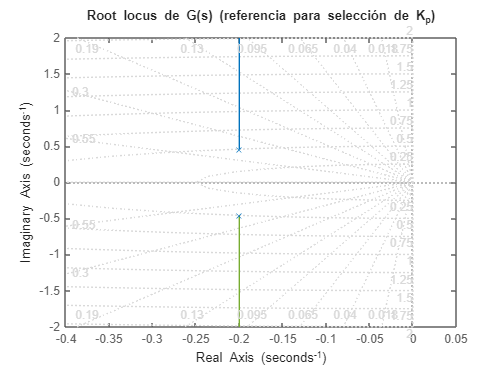


% Root locus global de la planta (referencia)
figure('Name','Root Locus de G(s)');
rlocus(G); grid on
title('Root locus de G(s) (referencia para selección de K_p)');